# simple Simoncelli and Heeger 1997 model

Description:

4 simple cells

2 are tuned to the same direction but with different phases

## build impulse response function

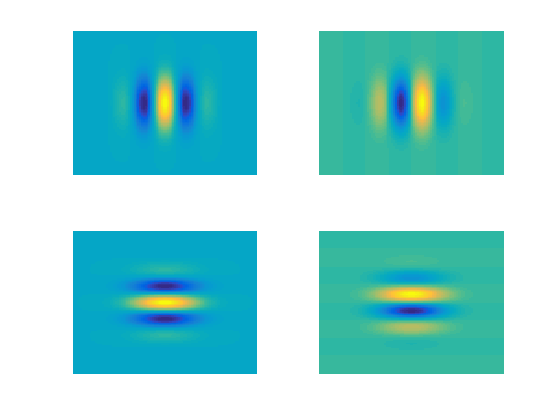

x     = -1 : 0.001 : 1;
m     = 0;
sigma = 0.1;
gauss = exp(-(x-m).^2./(2 * sigma).^2);
sigma = 0.2;
k     = 4;
alpha2 = 0;

% in the paper they used 3rd derivative gaussian as an impulse response
d1 = diff(gauss);
d2 = diff(d1);
d3 = diff(d2);
% but in here we are going to use gabors 

% generate gabors:
f = {};
T = 20;
% vertical filters
f{1} = repmat(makegabor2d(100, [], [], 4, pi/2, 0, 2), [1, 1, T]);
f{2} = repmat(makegabor2d(100, [], [], 4, pi/2, pi/2, 2), [1, 1, T]);
%horizontal filters
f{3} = repmat(makegabor2d(100, [], [], 4, pi, 0, 2), [1, 1, T]);
f{4} = repmat(makegabor2d(100, [], [], 4, pi, pi/2, 2), [1, 1, T]);

figure (1), clf
for k = 1 : 4
   subplot(2, 2, k), imagescs(f{k}(:, :, 1)), axis off 
end

## build stimuli

% up moving bar

stimuli = zeros(size(f{1}));
for t = 1 : T
    stimuli(50 - t, :, t) = 1;
end

## compute v1 simple cell linear response

for k = 1 : 4
    lrsp{k} = convn(f{k}, stimuli, 'same');
    lrsp{k} = lrsp{k}./sum(lrsp{k});
end

## compute v1 simple cell normalized response

hrsp = {};
nrsp = {};

hrsp = rectify(lrsp, T);
nrsp = normalize(hrsp, T, k, sigma);
% There is this question that which simple cells we should use as the normalization pool, all simple cells in the same location? All simple cells with the same location and the same orientation?

## compute V1 complex cell resopnse

crsp = nrsp;

## compute MT linear response

mtlrsp = crsp{1} + crsp{2} +crsp{3} + crsp{4} + alpha2;

## compute MT normalized response

% rectified response
mtlrsp(mtlrsp<0) = 0;
mthrsp = mtlrsp.^2;
mtnrsp = mthrsp./(mthrsp + sigma);

function output = rectify(input, T)
for k = 1 : 4
    for t = 1 : T
        % half-squaring
        tmp = input{k}(:, :, t);
        tmp(tmp<0) = 0;
        tmp = tmp.^2;
        output{k}(:, :, t) = tmp;
    end
end
end
% normalize-------------------------------------------------------------------
function output = normalize(input, T, k, sigma)
smp = @(k, t) input{k}(:, :, t);
for k = 1 : 4
    for t = 1 : T
        poolRsp =  smp(3, t) + smp(4, t) + smp(1, t) + smp(2, t) ;
        output{k}(:, :, t) =  k*input{k}(:, :, t)./(poolRsp + sigma.^2);
    end
end
end
    

